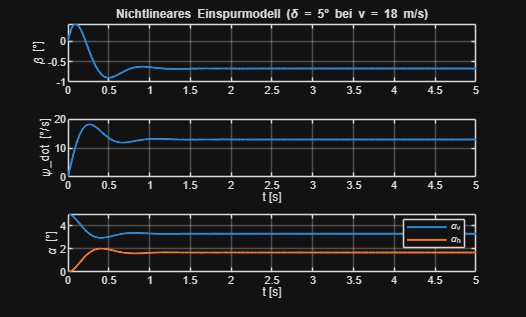

m = 2000;       % Masse [kg]
J = 4000;       % Massenträgheitsmoment Gierbewegung [kgm²]
lv = 1.43;      % Schwerpunktabstand zur Vorderachse [m]
lh = 1.4;       % Schwerpunktabstand zur Hinterachse [m]
cv = 70000;     % Schräglaufsteifigkeit Vorderachse [N/rad]
ch = 140000;    % Schräglaufsteifigkeit Hinterachse [N/rad]
v = 18;         % Fahrzeuggeschwindigkeit [m/s]

delta = deg2rad(5);   % Lenkwinkel [rad]

%% Simulation mit ode45
tspan = [0 5];
x0 = [0; 0];   % Anfangswerte: [beta0; psi_dot0]

odefun = @(t,x) bicycleNL(t,x,m,J,lv,lh,cv,ch,v,delta);
opts = odeset('RelTol',1e-7,'AbsTol',1e-9);
[t,x] = ode45(odefun, tspan, x0, opts);

beta    = x(:,1);      % [rad]
psi_dot = x(:,2);      % [rad/s]

%% Schräglaufwinkel nachträglich berechnen (aus beta(t), psi_dot(t))
cb = cos(beta);
cb(abs(cb) < 1e-6) = 1e-6;     % Schutz gegen Division durch 0

alpha_v = delta - (lv .* psi_dot) ./ (v .* cb) + tan(beta);
alpha_h =        (lh .* psi_dot) ./ (v .* cb) - tan(beta);

%% Umrechnung in Grad
beta_deg    = rad2deg(beta);
psi_dot_deg = rad2deg(psi_dot);
alpha_v_deg  = rad2deg(alpha_v);     % [°]
alpha_h_deg  = rad2deg(alpha_h);     % [°]

%% Plot
figure
subplot(3,1,1)
plot(t, beta_deg, 'LineWidth', 1.5)
grid on
ylabel('\beta [°]')
title('Nichtlineares Einspurmodell (\delta = 5° bei v = 18 m/s)')

subplot(3,1,2)
plot(t, psi_dot_deg, 'LineWidth', 1.5)
grid on
ylabel('\psi\_dot [°/s]')
xlabel('t [s]')

subplot(3,1,3)
plot(t, alpha_v_deg, 'LineWidth', 1.5)
hold on
plot(t, alpha_h_deg, 'LineWidth', 1.5)
grid on
ylabel('\alpha [°]')
xlabel('t [s]')
legend('\alpha_v','\alpha_h')


%% Lokale Funktion: Nichtlineare Modellgleichungen
function dx = bicycleNL(~, x, m, J, lv, lh, cv, ch, v, delta)

    beta    = x(1);   % Schwimmwinkel [rad]
    psi_dot = x(2);   % Giergeschwindigkeit [rad/s]

    % Schutz gegen cos(beta) -> 0
    cb = cos(beta);
    if abs(cb) < 1e-6
        cb = sign(cb) * 1e-6;
    end

    % Schräglaufwinkel
    alpha_v = delta - (lv*psi_dot)/(v*cb) + tan(beta);
    alpha_h =        (lh*psi_dot)/(v*cb) - tan(beta);

    % Nichtlineare Differentialgleichungen
    beta_dot = -psi_dot + (1/(m*v)) * (cv*alpha_v + ch*alpha_h);
    psi_ddot = (1/J) * (lv*cv*alpha_v*cos(delta) - lh*ch*alpha_h);

    dx = [beta_dot; psi_ddot];
end